# Algoritmos Numéricos por Computadora

# Primer parcial - Otoño 2019

Cambia el nombre del script a NombreClaveúnica (ej: Marcelo123456).

Sube tu archivo resultado a comunidad $\to$ primerParcial antes de las 10am.

## Formato IEEE 754. Punto flotante de doble precisión.

Explica a detalle la representación hexadecimal del número -8.75  en el  formato IEEE 754: $x=\mathrm{signo}\;\left(1+f\right)2^e$. En el siguiente código inserta tus observaciones y cálculos para determinar: *signo*, *e*, *f *y *x*. 

num = -8.75;
format hex
repHex = num2hex(num) 

repHex = 'c021800000000000'

format;
% Escribe aquí tus observaciones y cálculos
% signo = tomamos las primeras 3 cifras de la representación hexadecimal y
% la convertimos a binario en este caso es : 
% c02 que en binario = 1100 0000 0010, vemos si el ultimo bit es 1 entonces
% el signo será negativo.
aux = repHex(1:3)

aux = 'c02'

bin = hexToBinaryVector(aux,12)

bin = 1×12 logical array
   1   1   0   0   0   0   0   0   0   0   1   0


% e = para el exponente debemos utilizar las 11 cifras restantes del 1100 0000 0010
% convertirlo a decimal y a esas 11 cifras restarle 1023.
auxbin = bin(2:end)

auxbin = 1×11 logical array
   1   0   0   0   0   0   0   0   0   1   0


str_b = num2str(auxbin)

str_b = '1  0  0  0  0  0  0  0  0  1  0'

 dec = bin2dec(str_b) 

dec = 1026

 exp = dec - 1023

exp = 3

% f = para obtener la mantissa se debe multiplicar las cifras restantes del
% numero a convertir por 16 elevado a la potencia negativa de su posición
% comenzando de izquierda a derecha 
aux2 = repHex(4:end);
bin2 = hexToBinaryVector(aux2,52); % se obtiene el número en un vector de 52 bits.  
i=-1;
j=1;
a = 1;
b = 4;
suma = 0;
aux = bin2;
% A continuación se convertirá cada digito de la cadena en hexadecimal a
% binario y posteriormente multiplicarlo por 16 elevado al exponente que le
% corresponde
while (j < 13) 
    aux2 = aux(a:b);
    str = num2str(aux2); % Convertir un vector binario en string
    aux3 = bin2dec(str); % string binario a decimal
    aux4 = aux3*(16^i); 
    suma = suma + aux4;
    a=a+4;
    b=b+4;
    j=j+1;
    i = i-1;
end
suma

suma = 0.0938

% x = se utiliza la formula x = -(1+f)*2^e
num = -(suma + 1)*(2^exp)

num = -8.7500

## Convergencia del algorimo de proporción aurea 

Sabiendo que la sucesión$p_n$ converge a $p\;$con orden *α* y constante de error asintótica *λ* si


$$\lim_{n\longrightarrow \infty } \frac{\left|p_{n+1} -p\right|}{{\left|p_n -p\right|}^{\alpha } }=\lambda$$


demuestra que el algorimo de proporción aurea para encontrar el mínimo de una función converge linealmente ($\alpha =1$).  Determina además el valor de $\lambda$.

En la ecuación, *p* es el mínimo de la función y $p_n$ es la proximación al mínimo en el paso n. Si $p_n$ es el punto medio del intervalo [a,b] en el paso n, entonces $p_n$ es correcto con una incertidumbre igual a la mitad del intervalo. Entonces, el numerador del límite puede aproximarse por la mitad del tamaño del intervalo en el paso n+1 y el denominador por la mitad del tamaño del intervalo en el paso n.

% a |---------------|b d = b-a 
% d = g*d  g = 0.68 = lambda 
% g es el factor que está recortando el intervalo  porque en cada iteración
% se multiplica por g.
%  |Pn+1 - P | = g* |Pn+1 - P|
%  |Pn+1 - P |^1 = g 
% ---------------
%   |Pn - P |

## Modelado de sistemas físicos. Movimiento en caída libre con aceleración constante. 

En Acapulco, clavadistas saltan al mar desde un risco (Ohanian & Markert, "Física para ingeniería y ciencias"). 

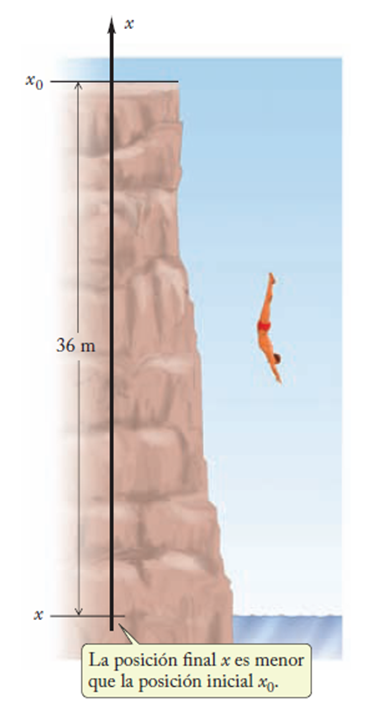

Sabiendo que $\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }x$$=-g$ y que $x\left(0\right)=x_0$, $v\left(0\right)=v_o$, obtén las ecuaciones que modelan la posición *x* y la velocidad *v* de los cavadistas. 

% a = g 
% la 2da derivada era la ecuación y las siguientes son las 2 condiciones iniciales. 
syms x(t) V(t) g x0 v0
eqn = diff(x,t,2) == -g

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-g$$

Dx = diff(x,t,1)

$$Dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

cond = [x(0)==x0, Dx(0)==v0]

$$cond = \left(\begin{array}{cc} x\left(0\right)=x_{0} & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=v_{0} \end{array}\right)$$

xSol(t) = dsolve(eqn,cond)

$$xSol(t) = -\frac{g\,t^{2}}{2}+v_{0}\,t+x_{0}$$

vP = diff(xSol,t)

$$vP(t) = v_{0}-g\,t$$

Suponiendo que la velocidad inicial es cero, que los clavadistas caen desde una altura de 36m y que g=9.81m/s, aplica las ecuaciones encontradas para determinar ¿durante cuánto tiempo caen? ¿A qué velocidad entran al agua?

v0 =0;
x0=36;
g = 9.81;

xS = subs(xSol) 

$$xS(t) = 36-\frac{981\,t^{2}}{200}$$

vS = subs(vP)

$$vS(t) = -\frac{981\,t}{100}$$


xF = matlabFunction(xS) % funciones anonimas 

xF = function_handle with value:
    @(t)t.^2.*(-9.81e+2./2.0e+2)+3.6e+1


vF = matlabFunction(vS)

vF = function_handle with value:
    @(t)t.*(-9.81e+2./1.0e+2)


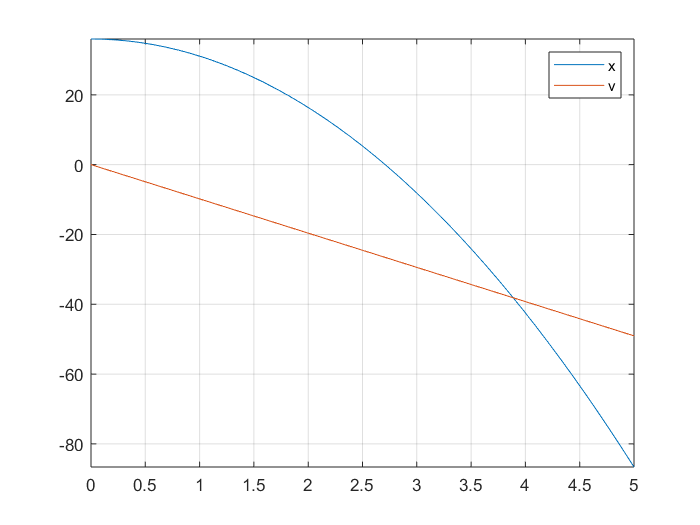

fplot(xF,[0,5])
hold on;
fplot(vF,[0,5])
legend('x', 'v');
grid on;
hold off;

[t,i] = NewtonRaphson(xF,2,3)

t = 2.7091

i = 5

v = vF(t)

v = -26.5767


%Cuando llega al mar x=0 entonces cae durante :
t = sqrt(2*x0/g)

t = 2.7091

% llega a una velocidad de:
v = v0-g*t

v = -26.5767

## Raíces de una ecuación

Encuentra las tres raíces del polinomio:


$$p\left(x\right)=x^3 -15x-4$$


Primero grafica la función en el intervalo [-4,5] para ver la localización aproximada (o exacta) de las raíces. Después usa el algoritmo de Newton-Raphson (cuyo código se encuentra al final de este script) para encontrar las raíces.

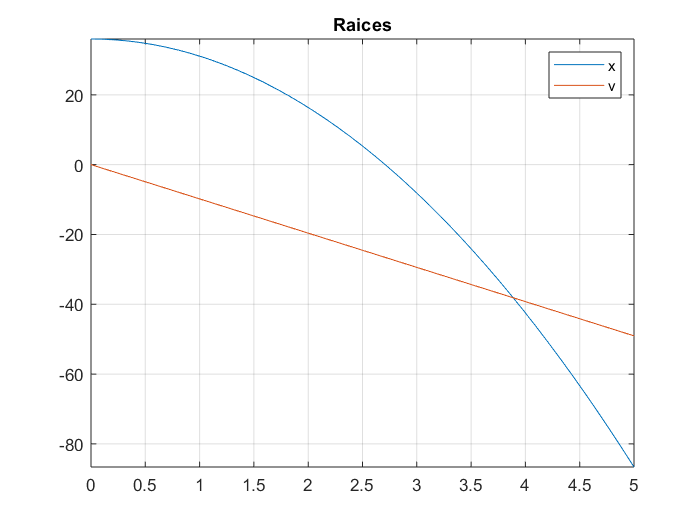

p = @(x) x.^3-15*x - 4;
a = -4; b = 5;
title('Raices');

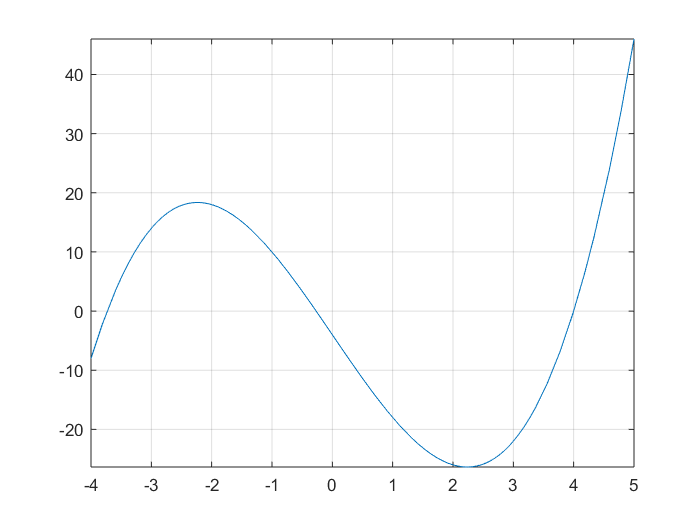

fplot(p,[a,b]);
grid on;

disp("Primer raíz")

Primer raíz


[x,~] = NewtonRaphson(p,-4,-3)

x = -3.7321

disp("Segunda raíz")

Segunda raíz


[x,~] = NewtonRaphson(p,-1,0) 

x = -0.2679

disp("Tercer raíz")

Tercer raíz


[x,~] = NewtonRaphson(p,3,5)

x = 4

## Algoritmo aproximado iterativo

El algoritmo más simple para encontrar el valor propio $\lambda$ más grande (radio espectral) de una matriz *A*  y el vector propio *x* asociado es el método de la potencia. El algoritmo inicia con un vector unitario aleatorio $x_1$ que posteriormente multiplica por *A* y normaliza $x_n =\frac{\mathrm{A}x_n }{\left\|\mathrm{A}{\mathrm{x}}_n \right\|}=\frac{Ax_n }{\mathrm{norm}\left(Ax_n \right)}$ repetidamente. 

El cociente de Rayleigh $\frac{x_n^' \cdot A{\mathrm{x}}_n }{x_n^' {\cdot x}_n }=$ $\frac{\mathrm{dot}\left(x_n ,Ax_n \right)}{\mathrm{dot}\left(x_n ,x_n \right)}$  es la aproximación $\lambda_n$correspondiente a $x_n$. 

Escribe la función powerMethod que implementa este algoritmo (más abajo en el script). 

Usa la función para encontral el radio espectral de *A= gallery(3)*. Comprueba la solución aplicando la definición de vector y valor propio: $\mathrm{Ax}=\lambda x$. Verifica la solución utilizando funciones de Matlab.

% Usa la función powerMethod que escribiste para encontrar 
% el radio espectral de A = galllery(3)
A=gallery(3)

A =   -149   -50  -154
   537   180   546
   -27    -9   -25


x =    -0.1429
    1.0000
   -0.1837


lambda = 3.0801

comprobacion = 3×1 logical array
   1
   1
   1


absoluto = 3.0000

auxlambda =    -0.4286
    3.0000
   -0.5510


auxA =    -0.4286
    3.0000
   -0.5510


radioEspectral = 3.0000

aux =    -0.4286
    3.0000
   -0.5510


aux2 =    -0.4286
    3.0000
   -0.5510



[x,lambda] = powerMethod(A)

% Comprueba la solución aplicando la definición de vector y valor propio
Ax = A*x;
lx = lambda*x;
resta = Ax - lx;
comprobacion = abs(resta)> eps()
% Verifica la solución utilizandofunciones de Matlab
%1) eig diag max x lambda 
eigen = eig(A);
absoluto = max(abs(eigen))
auxlambda = absoluto*x
auxA = A*x
% 2) polinomio caracteristico P roots(p) max det ( A -lambda i)
p = poly(A);
l = roots(p); 
radioEspectral = max(abs(l))
aux = radioEspectral*x
aux2 = A*x


Escribe aquí la función Power Method

function [x, lambda] = powerMethod(A)
% A*x = lambda*x  valor absoluto de eso menos lo otro >EPS
lambda = inf;
aux = size(A);
aux2 = aux(1,2);
v= rand(aux2,1); %x= rand/norma(v)
x = v/norm(v);
lambdaP=1;
tol = eps();
MAX =500;
i=0;
cond = true;
while cond
   lambdaP = lambda;
   Ax = A*x;
   xn = Ax/norm(Ax);
   lambda = dot(xn,Ax)/dot(xn,xn);
   x = Ax/max(abs(Ax));
   i= i+1;
   cond= abs((lambda- lambdaP)/lambda)>tol && i<MAX; % 2 condiciones :  lambda - lambdaprevia/ lambda > tol // valor maximo absoluto de las diferencias de x y xP   }
end
end

Método de Newton-Raphson

function [x,i] = NewtonRaphson(f,a,b)
% Computes approximate solution of f(x)=0
% Input: function handle f; a,b such that a<b (and ideally f(a)*f(b)<0)
% Output: Approximate solution x

    fsym = sym(f);
    dfs = diff(fsym);
    df = matlabFunction(dfs);   
    
    tol = eps;
    MAX = 53;
    x=(a+b)/2;
    i=0;
    condition = true;
    while condition                     % Evaluate solution     
        xp = x;                         % Needs improvement
        x = xp - f(xp)/df(xp);          % Modify solution       
        i = i + 1;
        condition = abs((x-xp)/x)>tol && f(x)~=0 && i<MAX;  
    end
end